% Cleanup!
clear all 
close all
clc

[MotionData]=ParseMatlabApp('1min50hz_nathan_c.mat')

MotionData = struct with fields:
            Accel: [3393×3 double]
      Orientation: [3392×3 double]
           AngVel: [3392×3 double]
          t_Accel: [3393×1 double]
    t_Orientation: [3392×1 double]
         t_AngVel: [3392×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


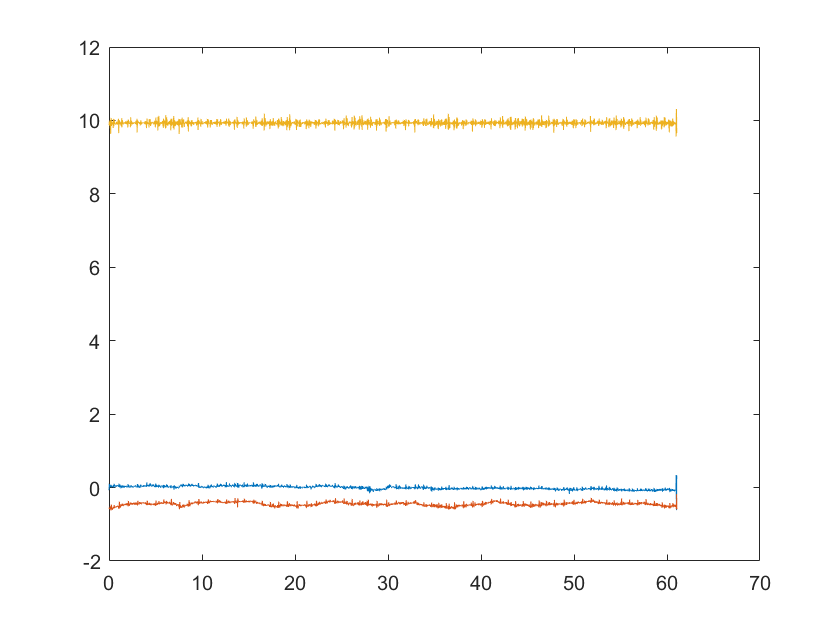

plot(MotionData.t_Accel, MotionData.Accel)


Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

N = length(MotionData.t_Accel)

N = 3393



[chunked_t_Accel,chunked_Accel] = TrimMotionData(MotionData,1)

Fs = 55.5556

N = 3393

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 1

index_front = 57

MotionData = struct with fields:
            Accel: [3393×3 double]
      Orientation: [3392×3 double]
           AngVel: [3392×3 double]
          t_Accel: [3337×1 double]
    t_Orientation: [3392×1 double]
         t_AngVel: [3392×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t_Accel = 1×1 cell array
    {3333×1 double}


chunked_Accel = 1×1 cell array
    {3333×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(MotionData.t_Accel)

N = 3393

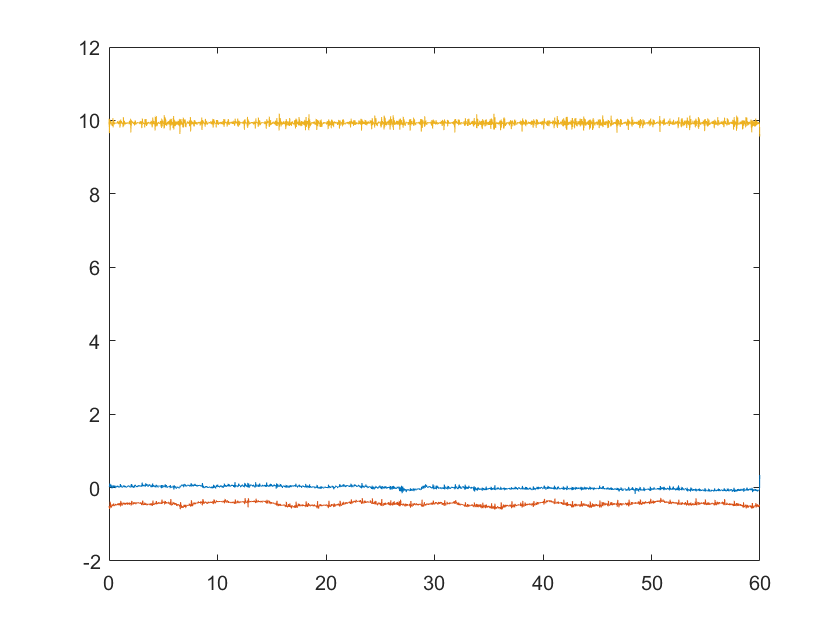

plot(chunked_t_Accel{1}, chunked_Accel{1})

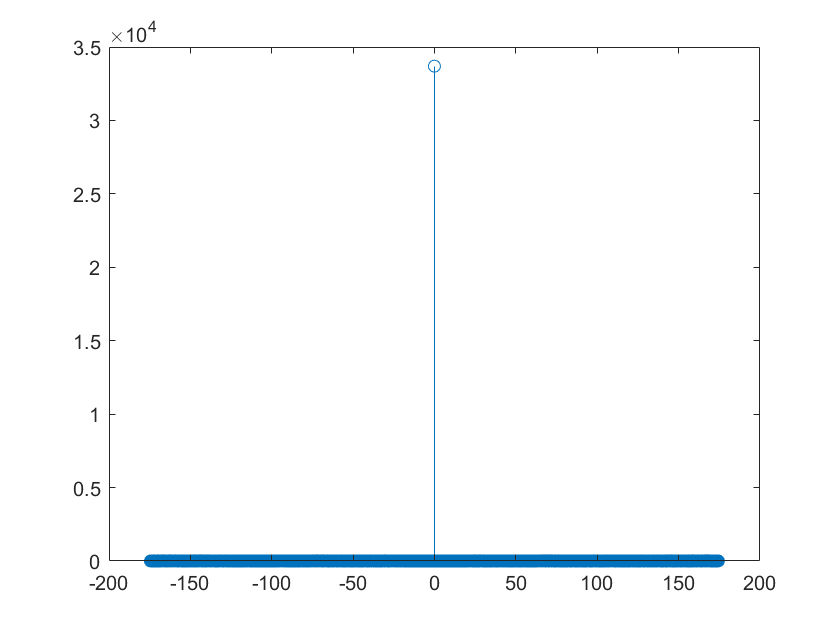

z_fft = fft(MotionData.Accel(:, 3));
z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+04 *

    3.3696
    0.0017
    0.0017
    0.0013
    0.0013


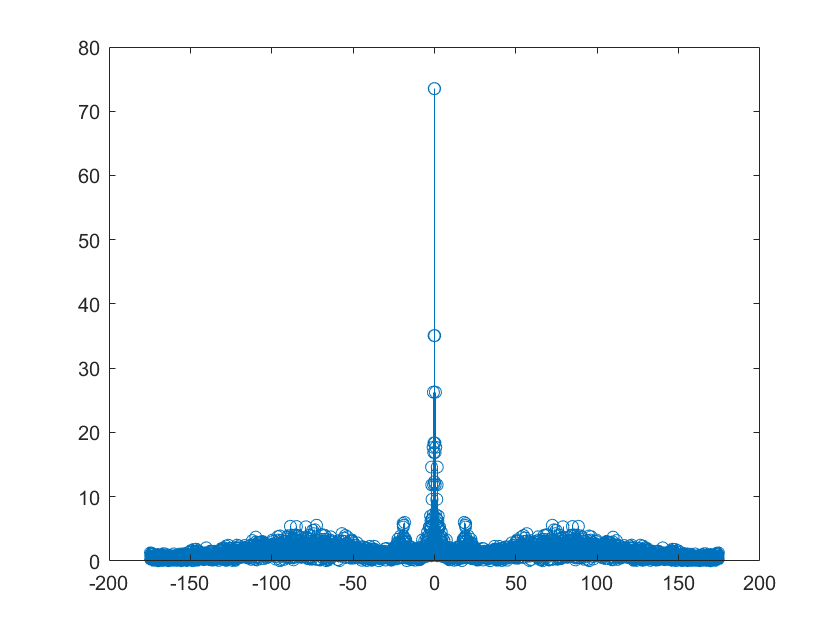

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = abs(fftshift(y_fft));
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

breath_low = 8/60

breath_low = 0.1333

breath_high = 20/60

breath_high = 0.3333

hb_low = 40/60

hb_low = 0.6667

hb_high = 100/60

hb_high = 1.6667

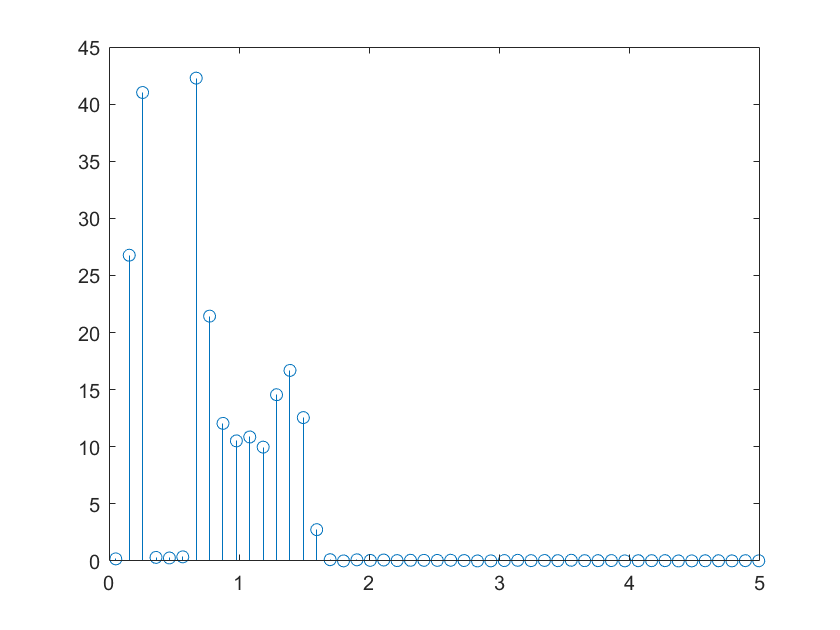


filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/100;

stem(frequencies_shifted, y_fft_shift)
xlim([0 5])